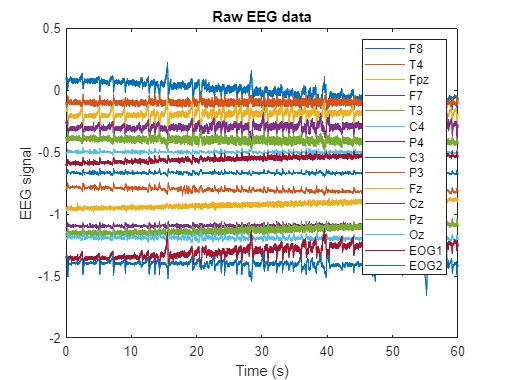

% Load the data file 'eegdata.mat'
load('eegdata.mat');

% Plot the raw EEG data using the time vector 't'
figure;
plot(t, signal + spread);
xlabel('Time (s)');
ylabel('EEG signal');
title('Raw EEG data');
legend(channelnames);

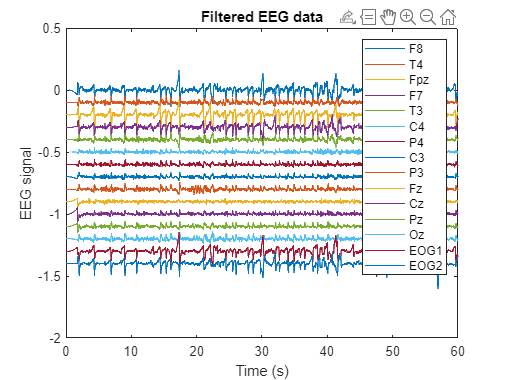

% Apply the FIR LP filter to the raw EEG data
lp_filtered_signal = filter(lp_filter(), signal);

% Apply the IIR notch filter as a forwards & backwards filter for the LP filtered signal
f_coeffs = coeffs(notch_filter());
notch_filtered_signal = filtfilt(f_coeffs.Numerator, f_coeffs.Denominator, lp_filtered_signal);

% Apply the FIR HP filter for the notch filtered signal
hp_filtered_signal = filter(hp_filter(), notch_filtered_signal);

% Plot the final LP, notch, and HP filtered EEG signal using the time vector 't'
figure;
plot(t, hp_filtered_signal + spread);
xlabel('Time (s)');
ylabel('EEG signal');
title('Filtered EEG data');
legend(channelnames);

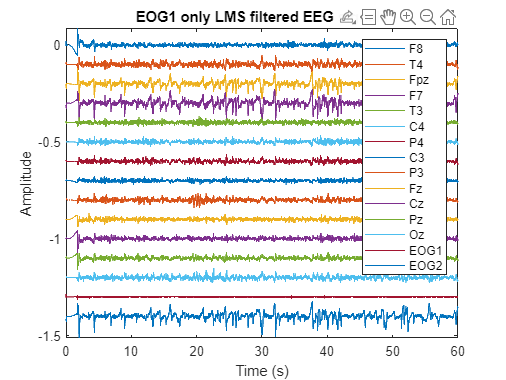

% Define the LMS filter object
LMSfilter = dsp.LMSFilter(11, 'Method', 'LMS', 'StepSize', 0.6, 'WeightsOutputPort', false);

%
[num_samples, num_channels] = size(signal);
num_iterations = 10;

% Filter each channel individually using the EOG1 channel
eog1_channel = hp_filtered_signal(:, strcmp(channelnames, 'EOG1'));
eog1_lms_filtered = zeros(num_samples, num_channels);

for i = 1:num_channels
    % Get the current channel name
    channel_name = channelnames{i};
    
    % Filter the current channel using the EOG1 channel
    eeg_channel = hp_filtered_signal(:, i);
    for j = 1:num_iterations
        [out1, out2] = step(LMSfilter, eog1_channel, eeg_channel);
    end
    
    % Store the EOG1 only LMS filtered EEG signals
    eog1_lms_filtered(:, i) = out2;
end

% Plot the EOG1 only LMS filtered EEG signals
figure;
plot(t, eog1_lms_filtered + spread);
axis tight;
xlabel('Time (s)');
ylabel('Amplitude');
title('EOG1 only LMS filtered EEG signals');
legend(channelnames);

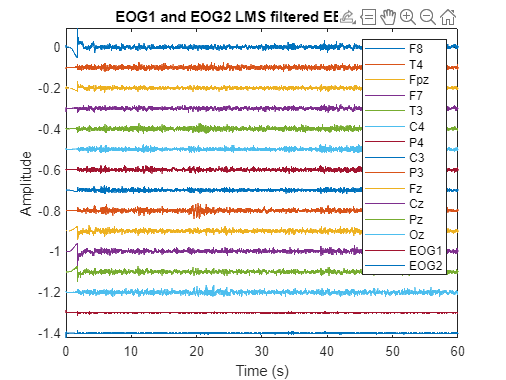

% Filter the EEG data again using the EOG2 channel
eog2_channel = eog1_lms_filtered(:, strcmp(channelnames, 'EOG2'));
eog2_lms_filtered = zeros(num_samples, num_channels);

for i = 1:num_channels
    % Get the current channel name
    channel_name = channelnames{i};
    
    % Filter the current channel using the EOG1 channel
    eeg_channel = eog1_lms_filtered(:, i);
    for j = 1:num_iterations
        [out1, out2] = step(LMSfilter, eog2_channel, eeg_channel);
    end
    
    % Store the EOG1 only LMS filtered EEG signals
    eog2_lms_filtered(:, i) = out2;
end


% Plot the EOG1 and EOG2 LMS filtered EEG signals
figure;
plot(t, eog2_lms_filtered + spread);
axis tight;
xlabel('Time (s)');
ylabel('Amplitude');
title('EOG1 and EOG2 LMS filtered EEG signals');
legend(channelnames);

rng(42);
[IC, A, W] = fastica(hp_filtered_signal');

Number of signals: 15
Number of samples: 12000
Calculating covariance...
Dimension not reduced.
Selected [ 15 ] dimensions.
Smallest remaining (non-zero) eigenvalue [ 1.237e-07 ]
Largest remaining (non-zero) eigenvalue [ 0.00346904 ]
Sum of removed eigenvalues [ 0 ]
[ 100 ] % of (non-zero) eigenvalues retained.
Whitening...
Check: covariance differs from identity by [ 1.94368e-11 ].
Used approach [ defl ].
Used nonlinearity [ pow3 ].
Starting ICA calculation...
IC 1 .............................................computed ( 45 steps ) 
IC 2 ..........computed ( 10 steps ) 
IC 3 .............computed ( 13 steps ) 
IC 4 ........computed ( 8 steps ) 
IC 5 ......computed ( 6 steps ) 
IC 6 .........................computed ( 25 steps ) 
IC 7 ......................computed ( 22 steps ) 
IC 8 .................................computed ( 33 steps ) 
IC 9 ...............................computed ( 31 steps ) 
IC 10 ..................computed ( 18 steps ) 
IC 11 .............computed ( 13 steps ) 
IC

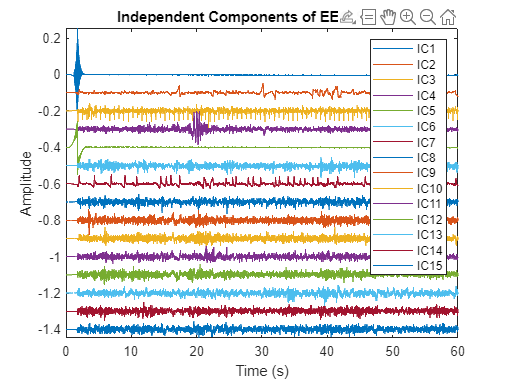


figure;
plot(t, IC' ./ 100 + spread);
axis tight;
xlabel('Time (s)');
ylabel('Amplitude');
title('Independent Components of EEG Signals');
legend("IC" + [1:size(IC,1)])

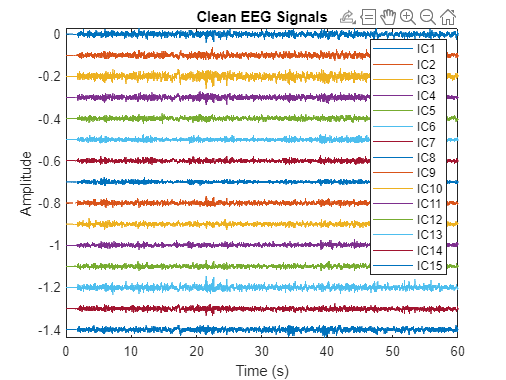

% Identify and remove artifacts
IC_artifacts = [1, 2, 3, 4, 5, 7];
IC(IC_artifacts, :) = 0;

clean_signal = A * IC;

plot(t, clean_signal' + spread);
axis tight;
xlabel('Time (s)');
ylabel('Amplitude');
title('Clean EEG Signals');
legend("IC" + [1:size(IC,1)])